# TITLE: Signal Modulation and Detection in an AWGN Channel with Probabilistic Constellation Shaping

Authors: Fernando Guiomar [guiomar@av.it.pt](guiomar@av.it.pt) 

Last Update: 09/11/2019

## Initialization

clear;
clear global;
close all;
clc;

% Load Libraries:
addpath(genpath('..\..\..\'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 10-Nov-2019 01:30:09


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


RGB = fancyColors();

## Input Parameters

SIG.M = 64;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.bitRate_net = 200e9;    % net bit-rate [Gbps]
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^17;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol
laserLW = 0e6;              % laser linewidth [Hz]

FEC_rate = 5/6;             % FEC rate

pilotRate = 1;              % Pilot rate
useCPE2 = false;            % flag to decide whether to use 2nd CPE or not

SNR_dB = 12;                % SNR in dB

## Set Transmitter Parameters

#### Signal Parameters:

nBpS_net = SIG.bitRate_net / (SIG.nPol*SIG.symRate*FEC_rate*pilotRate);
TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',nBpS_net,'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

#### LASER Parameters:

TX.LASER.linewidth = laserLW;

#### DSP Pilots Parameters:

TX.PILOTS.active = true;
TX.PILOTS.rate = pilotRate;
TX.PILOTS.option = 'outerQPSK';
% TX.PILOTS.scaleFactor = 1;

#### FEC Parameters:

TX.FEC.active = false;
TX.FEC.rate = FEC_rate;
TX.FEC.nIter = 50;

#### PCS Parameters:

TX.PCS.method = 'CCDM';

## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,txSyms,TX.QAM] = Tx_ProbShaping(TX.BIT.txBits,TX.QAM,TX.SIG,TX.FEC.rate);

#### Plot Transmitted Constellation Symbols:

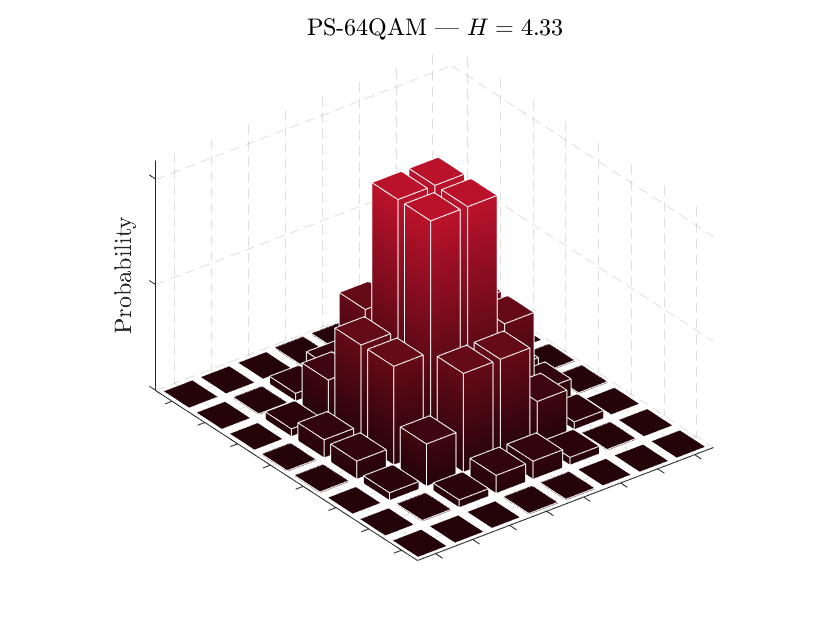

plotProbShaping_PDF_const('const',TX.QAM.IQmap,'symbols',txSyms(:),'color',RGB.itred);

## Add DSP Pilots

if isfield(TX,'PILOTS') && TX.PILOTS.active && TX.PILOTS.rate < 1
    [S.tx,TX.PILOTS] = Tx_addPilots(S.tx,TX.PILOTS,TX.QAM.IQmap);
    TX.QAM.meanConstPower = mean(abs(S.tx).^2,2);
    TX.QAM.maxConstPower = max(abs(S.tx).^2,[],2);
end

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps

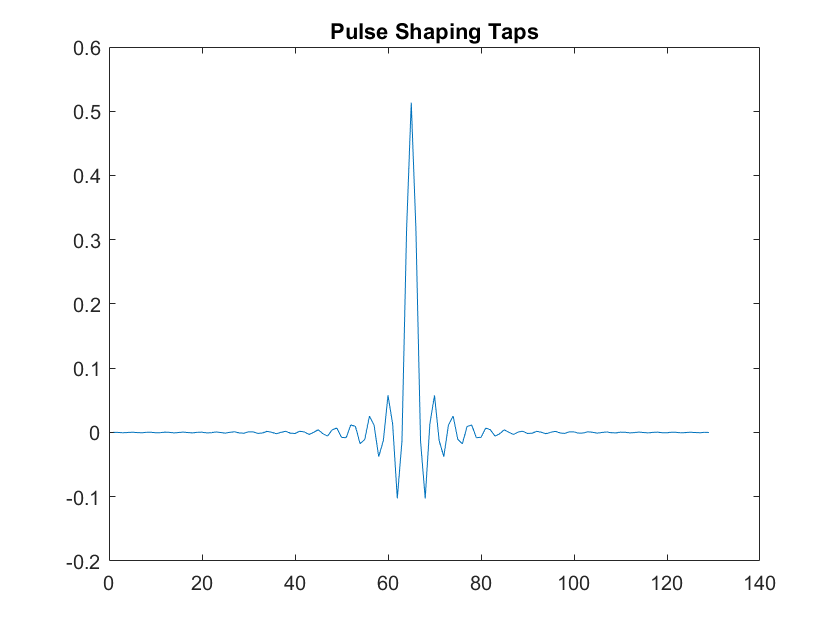

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum

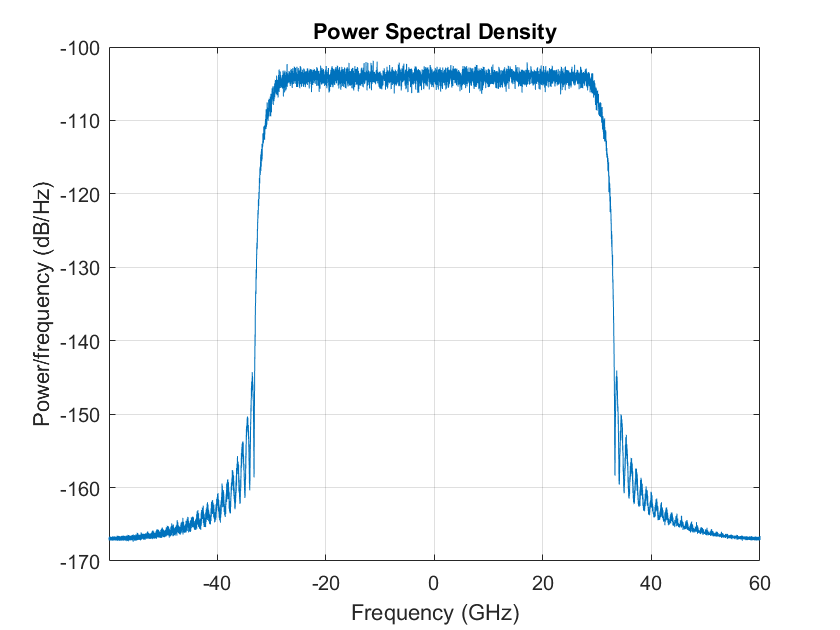

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

## Digital-to-Analog Converter

Fs_SC = nSpS * SIG.symRate;
[S.txSC,TX.DAC] = Tx_DAC(S.txSC,TX.DAC,Fs_SC);

## Apply Laser

nSamples = size(S.tx,2) * nSpS;
[Scw,TX.LASER] = laserCW(TX.LASER,Fs_SC,nSamples);
nPol = size(S.txSC,1);
if nPol == 2
    Scw = Scw/sqrt(2);      % divide CW power by 2 if dual-pol
end
for n = 1:nPol
    S.txSC(n,:) = Scw.*S.txSC(n,:);
end

#### Plot Laser Phase Noise

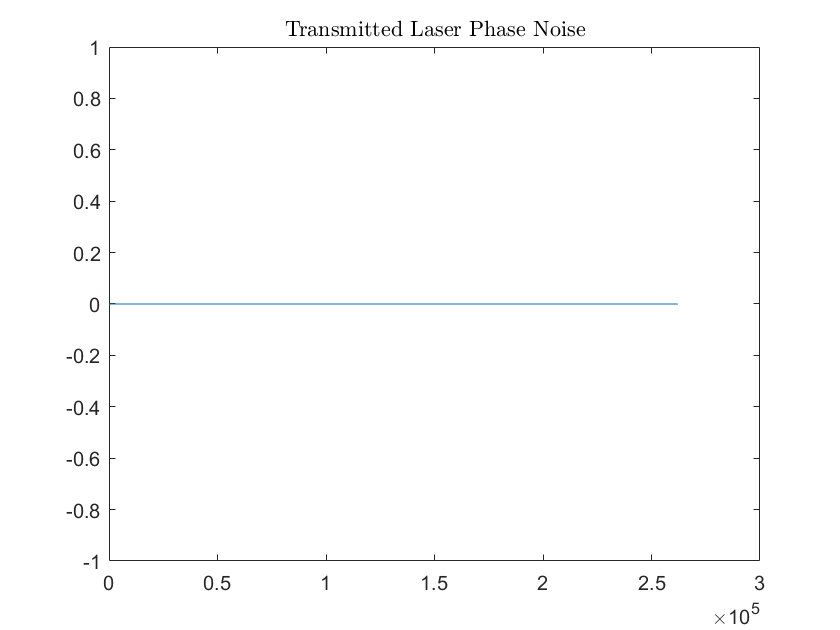

figure();
plot(TX.LASER.phaseNoise)
title('Transmitted Laser Phase Noise','interp','latex')

## Set SNR

S.rx = setSNR(S.txSC,SNR_dB,TX.DAC.RESAMP.sampRate,SIG.symRate);

#### Plot Received Signal Spectrum:

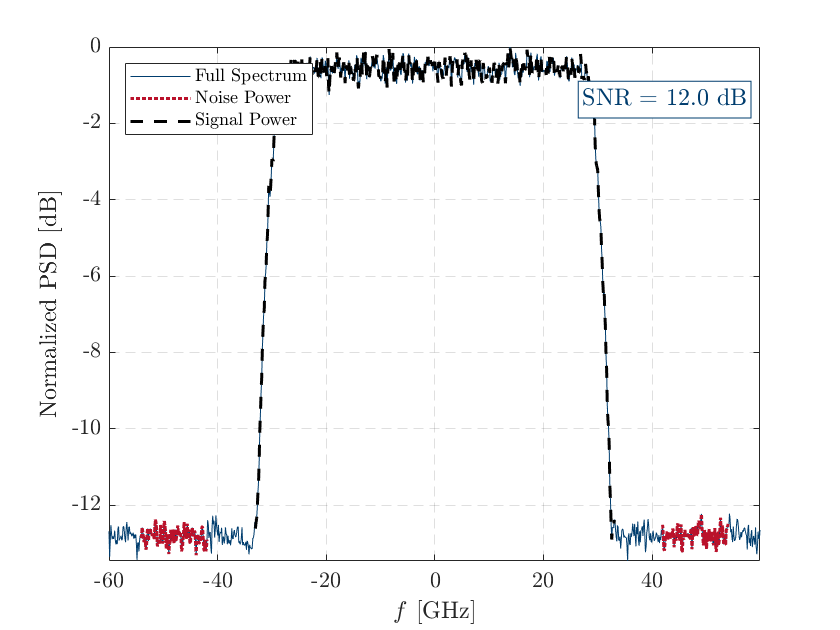

Sf = pwelch(S.rx,1e3,[],[],Fs_SC,'centered','psd').';
[SNR_rx_dB,Ps,Pn] = SNR_estimateFromSpectrum(Sf,Fs_SC,TX.SIG.symRate,...
    TX.SIG.rollOff,[-0.9 -0.7; 0.7 0.9],0,true);

## Set DSP Parameters

%% Matched-Filter:
DSP.MF.type = 'RRC';
DSP.MF.rollOff = TX.SIG.rollOff;

%% Carrier-Phase Estimation - 1st Stage:
DSP.CPE1.method = 'pilot-based:optimized';
DSP.CPE1.decision = 'data-aided';
% DSP.CPE1.nTaps = 15;
DSP.CPE1.nTaps_min = 1;
DSP.CPE1.nTaps_max = 201;
DSP.CPE1.PILOTS = TX.PILOTS;

%% Carrier-Phase Estimation - 1st Stage:
% DSP.CPE2.method = 'BPS:optimized';
DSP.CPE2.method = 'BPS';
DSP.CPE2.nTaps = 22;
DSP.CPE2.nTaps_min = 1;
DSP.CPE2.nTaps_max = 501;
DSP.CPE2.nTestPhases = 10;
DSP.CPE2.angleInterval = pi/8;

%% Demapper:
DSP.DEMAPPER.normMethod = 'MMSE';

## Apply Matched Filter

S.rx = LPF_apply(S.rx,DSP.MF,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Downsample to 1 Sample/Symbol

S.rx_1sps = S.rx(1:nSpS:end);

## Apply 1st-Stage CPE: Pilot-Based

if pilotRate < 1
    [S.rx_1sps,DSP.CPE1] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE1);
end

## Apply 2nd-Stage CPE: Blind-Phase Search

C = TX.QAM.IQmap;
if useCPE2
    [S.rx_1sps,DSP.CPE2] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE2,C);
end

## Remove DSP Pilots

if pilotRate < 1
    [S.rx_1sps,S.tx] = pilotSymbols_rmv(S.rx_1sps,S.tx,DSP.CPE1.PILOTS);
end

## Apply Symbol Demapper

[DSP.DEMAPPER,S.tx] = symDemapper(S.rx_1sps,S.tx,C,DSP.DEMAPPER);

#### Calculate Error Vector Magnitude (EVM):

EVM = EVM_eval(S.rx_1sps,S.tx);

#### Calculate Mutual Information (MI) and Generalized Mutual Information (GMI):

MI = MI_eval(S.rx_1sps,S.tx,DSP.DEMAPPER.C,DSP.DEMAPPER.N0,TX.QAM.symProb);
[GMI,NGMI] = GMI_eval(S.rx_1sps,DSP.DEMAPPER.txBits,DSP.DEMAPPER.C,DSP.DEMAPPER.N0,TX.QAM.symProb);

#### Plot Constellation after Demapping:

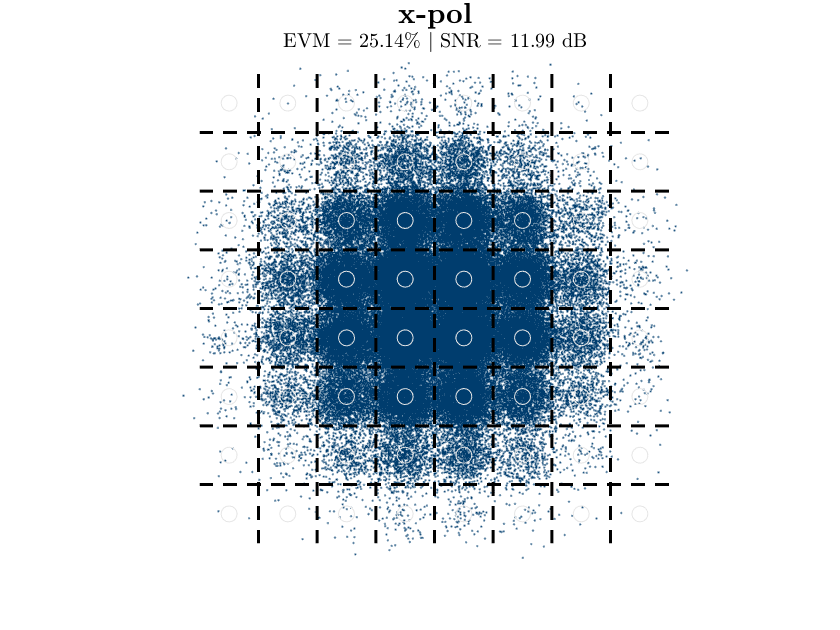

scatterPlot(S.rx_1sps,'EVM',EVM,'const',DSP.DEMAPPER.C);

## AWGN Theory

EVMt = 10^(-SNR_dB/20)*100;
[NGMIt,GMIt,MIt] = snr2gmi(SNR_dB,SIG.M,TX.QAM.entropy);

## Print Results

entranceMsg('RESULTS');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                             RESULTS                              %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


fprintf('\nEVM (theory): %1.3f%%',EVMt);


EVM (theory): 25.119%

fprintf('\nEVM: %1.3f%%',EVM);


EVM: 25.140%

fprintf('\n\nMI (theory): %1.3f',MIt);



MI (theory): 3.886

fprintf('\nMI: %1.3f\n',MI);


MI: 3.883


fprintf('\nGMI (theory): %1.3f\n',GMIt);


GMI (theory): 3.886


fprintf('\nGMI: %1.3f\n',GMI);


GMI: 3.883


fprintf('\nNGMI (theory): %1.3f\n',NGMIt);


NGMI (theory): 0.925


fprintf('\nNGMI: %1.3f\n',NGMI);


NGMI: 0.925


## Exit PROG

exitProg();



Total Elapsed Time: 17.2457 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
